4.2.19

k=10
for i=1:k
    svd(randn(5,4))
end

4.2.20

A=randn(8,4);
A(:,5:6)=A(:,1:2)+A(:,3:4);
[Q,R]=qr(randn(6));
A=A*Q

a)no

b)

format short e;
svd(A)

c)

rank(A)

d)

rank(A,10^-17)

4.2.21

a)largest main diagonal entry is a11 and smallest is ann=s^(n-1)

sin(1.2)^89

b)

A=gallery('kahan',90,1.2,0)
format short e
sig=svd(A)

rank(A)

c)

A=gallery('kahan',90,1.2,25)
format short e
sig=svd(A)

rank(A)

[Q,R,E]=qr(A);
dif=norm(eye(90)-E)
R
R(90,90)

The theoretical rank of A is 90

Its numerical rank by taking tolerance as epsilon*|sigma1| is 89 which is shown by the rank command

But when we do rank revealing QR decomposition,it showed rank to be 90

load clown.mat;
X

X =      2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2
    61    69    69    69    69    69    69    69    69    69    69    69    69    69    61    69    61    69    69    69    61    61    61    69    61    69    61    69    61    69    61    61    61    69    61    61    61    69    61    69    61    69    61    69    61    61    61    61    55    61
    69    61    69    61    69    59    69    59    69    69    69    59    69    43    61    59    69    61    69    59    69    55    61    55    61    59    69    69    69    61    69    59    69    61    69    61    69    55    61    59    69    59    61    55    69    43    61    43    61    43
    61    69    61    61    56    61    61    61    61    69    61    69    61    61    61   

[U, S, V] = svd(X)

U =   -4.1774e-03  -2.4165e-03  -3.2882e-03  -1.8505e-03   1.1921e-03  -2.1356e-03   1.2538e-03  -3.0057e-05   1.3124e-03  -1.8374e-03   1.6681e-03  -2.9291e-03   4.1778e-04  -1.7958e-03   7.3257e-04   3.3627e-03  -1.3227e-03   2.2682e-03   4.3360e-03  -1.0268e-03   3.5158e-03  -2.6482e-03   4.7680e-03  -1.1463e-03   3.7162e-03  -6.2610e-04   9.0082e-04  -8.0042e-04   3.5758e-03  -6.3828e-04   2.6541e-03  -2.6672e-03   3.7379e-03   2.5910e-03  -2.1555e-03   2.6780e-03   1.1039e-03   1.0779e-03   6.6893e-03  -2.3947e-03  -1.5019e-03   3.3874e-03  -1.5579e-03   3.7042e-03  -1.8045e-03   9.1553e-04  -8.8842e-03   3.5757e-04  -2.8639e-03   6.6518e-03
  -1.0573e-01  -1.5373e-01  -4.2668e-02   1.2353e-02  -7.2497e-02  -3.4482e-02   1.2980e-01   3.5123e-02   6.1313e-02  -8.2770e-02   1.0879e-01  -1.2688e-01   8.7486e-04   3.4285e-02  -5.2463e-02   7.5589e-02  -8.0531e-02   7.8989e-02   1.0133e-01  -9.1434e-03   1.1387e-01  -8.8269e-02   1.1542e-01  -1.1862e-01  -2.4629e-02  -1.0172e-03  -1.48

S =    8.1571e+03            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0
            0   2.0618e+03            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0            0       

V =   -3.2542e-02  -3.7265e-02  -4.4804e-02   4.6589e-02   1.5367e-02   1.9624e-02   7.3747e-02  -5.7809e-02  -2.7285e-02  -1.0270e-01  -2.0265e-02  -5.2487e-02   2.4588e-02   3.2921e-02  -4.1485e-02   3.5567e-02  -1.4323e-02  -7.3517e-02  -5.8404e-02  -2.3221e-02   9.3323e-02   1.7958e-03   5.5084e-02  -4.0910e-02  -5.6929e-02  -2.5551e-02  -5.1160e-02   1.5853e-02  -3.0037e-02  -1.1290e-02   3.2296e-02   2.2913e-02   6.7712e-02  -3.0966e-02   2.7468e-02  -9.4321e-02   4.6678e-02   4.5810e-02   9.8543e-03   1.9657e-04   9.2361e-02   2.6228e-02  -4.0011e-02   3.3489e-02   2.5857e-02  -2.4432e-03  -8.6484e-02  -6.3001e-02  -2.8511e-03   6.8655e-02
  -3.0609e-02  -4.0963e-02  -5.4726e-02   4.9856e-02   1.2009e-02   1.9661e-02   8.5658e-02  -2.6576e-02   4.6851e-02  -6.1913e-02  -6.4102e-03  -6.7681e-02   2.5214e-02   4.5903e-02  -4.3355e-02   2.4602e-02  -9.4528e-03  -4.3741e-02  -3.9146e-02  -2.2658e-02   6.0836e-02  -2.2922e-02   2.7401e-02  -4.1220e-02  -7.7658e-02  -5.0889e-02  -8.78

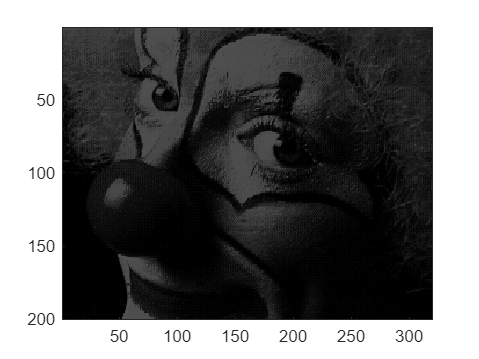

colormap('gray')

relerr=[];
compratio=[];
sig=svd(X)

sig =    8.1571e+03
   2.0618e+03
   1.7765e+03
   1.2676e+03
   1.1218e+03
   1.0699e+03
   8.9870e+02
   7.1227e+02
   6.8332e+02
   6.5267e+02


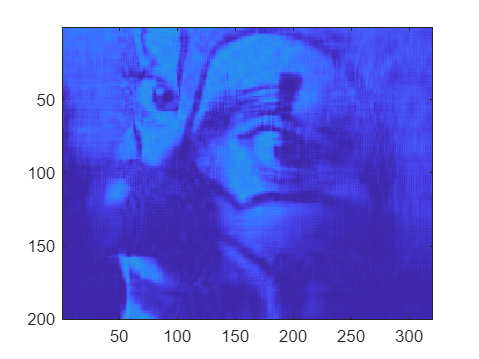

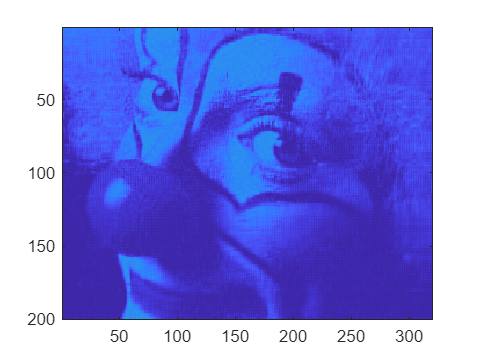

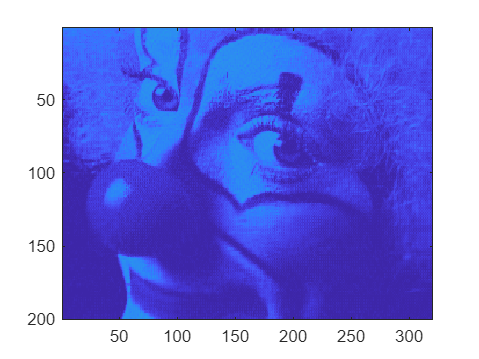

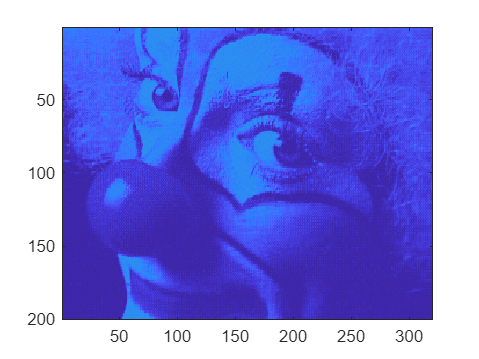

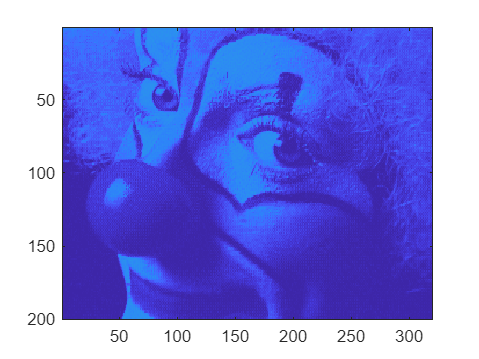

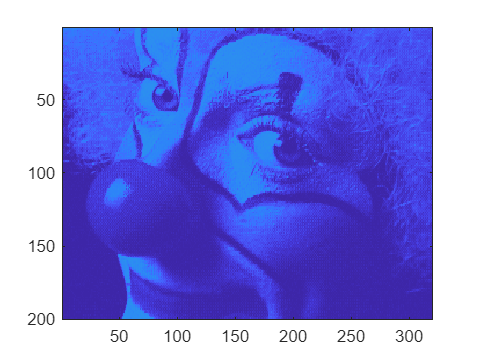

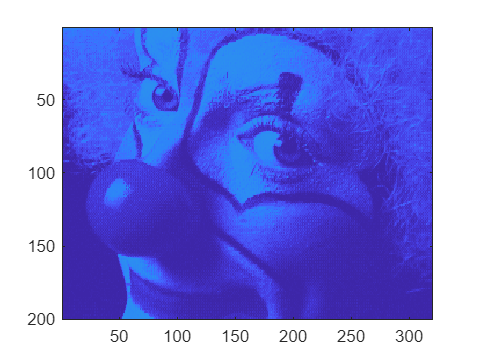

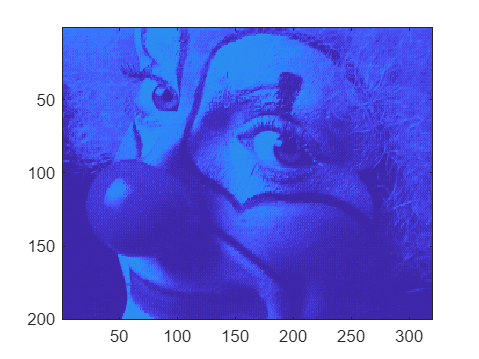

for k=[20:20:200]
    figure;
    image(U(:, 1:k)*S(1:k, 1:k)*V(:,1:k)')
    relerr(end+1)=sig(k)/sig(1);
    compratio(end+1)=520*k/6400;
end

table([20:20:200].',relerr.',compratio.','VariableNames',{'k','relative errors','compression ratio'})

ans = 10×3 table
        k         relative errors    compression ratio
    __________    _______________    _________________

    2.0000e+01      4.3269e-02          1.6250e+00    
    4.0000e+01      2.2500e-02          3.2500e+00    
    6.0000e+01      1.6840e-02          4.8750e+00    
    8.0000e+01      1.3369e-02          6.5000e+00    
    1.0000e+02      1.0585e-02          8.1250e+00    
    1.2000e+02      8.4336e-03          9.7500e+00    
    1.4000e+02      6.4951e-03          1.1375e+01    
    1.6000e+02      4.7517e-03          1.3000e+01    
    1.8000e+02      3.1465e-03          1.4625e+01    
    2.0000e+02      2.9503e-04          1.6250e+01    
